parpool(16)

Error using parpool
Found an interactive session. You cannot have multiple interactive sessions open simultaneously. To terminate the existing session, use delete(gcp('nocreate')).

calcu = [];
k = dir;
isd = {k(:).isdir};
name = {k(:).name};
isd = cell2mat(isd);
name = name(isd);
parfor i = 3:length(name)
    calcu(i).temp = name{i};
    data = imageDatastore(name{i},"FileExtensions",'.jpg');
    sprintf(name{i}+" :archivos :"+num2str(numel(data.Files)))
    restemp = zeros(1,numel(data.Files));
    for j = 1:numel(data.Files)
        imtep = imbinarize(rgb2gray(imread(data.Files{j})));
        imtep = imtep(110:end-110,25:end-25);
        area = min(size(imtep))*max(size(imtep));
        imtemp = bwarea(imtep);
        restemp(j) = imtemp/area;
    end
    calcu(i).res =  restemp;
end


ans = 


ans = 


ans = 

    "run_0.055 :archivos :1000"


ans = 


ans = 


ans = 


ans = 


ans = 


ans = 

    "run_0.065 :archivos :1000"


ans = 

    "run_0.015 :archivos :1000"


ans = 

    "run_0.075 :archivos :1000"


ans = 

    "run_0.045 :archivos :1000"


ans = 

    "run_0.025 :archivos :1000"


ans = 

    "run_0.035 :archivos :1000"


ans = 

    "run_0.085 :archivos :1000"


ans = 

    "run_0.050 :archivos :1000"

    "run_0.010 :archivos :1000"

    "run_0.040 :archivos :1000"

    "run_0.060 :archivos :1000"

    "run_0.020 :archivos :1000"

    "run_0.070 :archivos :1000"

    "run_0.080 :archivos :1000"

    "run_0.030 :archivos :1000"


ans = 

    "run_0.535 :archivos :1000"


ans = 


ans = 

    "run_0.445 :archivos :1000"


ans = 


ans = 

    "run_0.625 :archivos :1000"


ans = 


ans = 

    "run_0.175 :archivos :1000"


ans = 


ans = 

    "run_0.355 :archivos :1000"


ans = 


ans = 

    "run_0.715 :archivos :1000"


ans = 


ans = 

    "run_0.80

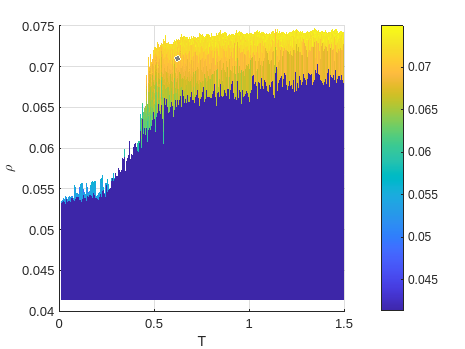

close all
[temp,t] = meshgrid(0.01:0.005:1.5,1:1000);
rho = zeros(1000,299);
for i = 1:numel(calcu)-2
    ter = calcu(i+2).res;
    rho(:,i) = ter;
end
s = surf(temp,t,rho,'EdgeColor','none');
xlabel("T")
ylabel("t")
zlabel("${\rho}$",'interpreter','latex')
view(0,0)
grid on
colorbar

  Name         Size               Bytes  Class     Attributes

  temp      1000x299            2392000  double              

